# Tutorial 9 -- Networks

## Import Edge Lists

I've created an edge list (or adjacency matrix) of two-grams from the Annotated Beethoven Corpus, which contains Roman numeral annotations for all of Beethoven's string quartets. Get it here: [https://github.com/DCMLab/ABC](https://github.com/DCMLab/ABC) 

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_09_networks\2share\tutorial_09_networks\data')
tab = readtable('ABC_majorRNroots_counts_edges.csv')

tab = 528×4 table
     source      target      Weight     piece_count
    ________    ________    ________    ___________

    {'V'   }    {'I'   }     0.21153         1     
    {'I'   }    {'V'   }     0.15505        14     
    {'ii'  }    {'V'   }    0.050608         5     
    {'I'   }    {'IV'  }    0.031506         4     
    {'IV'  }    {'V'   }    0.030431         4     
    {'viio'}    {'V'   }    0.028198         2     
    {'V'   }    {'IV'  }    0.023981         1     
    {'I'   }    {'ii'  }    0.022244         9     
    {'I'   }    {'viio'}    0.022244         5     
    {'vi'  }    {'V'   }    0.021996         1     
    {'V'   }    {'viio'}      0.0215         1     
    {'viio'}    {'I'   }    0.020342         4     
    {'V'   }    {'vi'  }    0.019681         2     
    {'V'   }    {'ii'  }    0.018358         1     
    {'I'   } 

## Directed Graphs

Create a directed graph for the top 10 edges.

G = digraph(tab.source(1:10),tab.target(1:10),tab.Weight(1:10),'OmitSelfLoops');

#### Visualization

Plot the graph.

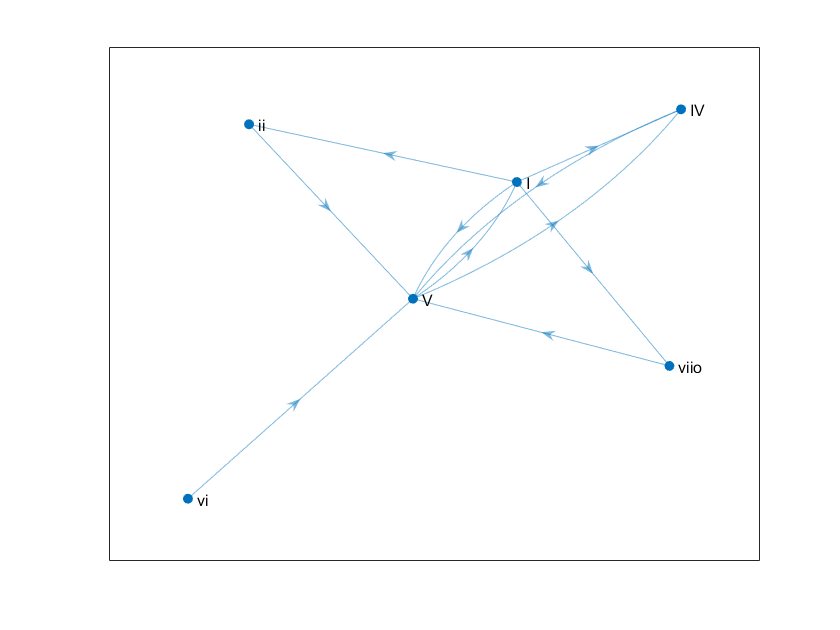

figure; plot(G,'Layout','force')

#### Graph Properties

Let's look at a few properties of the graph. We'll start by looking at the list of nodes and edges.

G.Nodes

ans = 6×1 table
      Name  
    ________

    {'V'   }
    {'I'   }
    {'ii'  }
    {'IV'  }
    {'viio'}
    {'vi'  }


G.Edges

ans = 10×2 table
          EndNodes           Weight 
    ____________________    ________

    {'V'   }    {'I'   }     0.21153
    {'V'   }    {'IV'  }    0.023981
    {'I'   }    {'V'   }     0.15505
    {'I'   }    {'ii'  }    0.022244
    {'I'   }    {'IV'  }    0.031506
    {'I'   }    {'viio'}    0.022244
    {'ii'  }    {'V'   }    0.050608
    {'IV'  }    {'V'   }    0.030431
    {'viio'}    {'V'   }    0.028198
    {'vi'  }    {'V'   }    0.021996


#### Traversals

Compute a traversal between two nodes. What's the distance between 'vi' and 'IV' in the graph?

[path,dist] = shortestpath(G,'vi','IV')

path = 1×3 cell array
    {'vi'}    {'V'}    {'IV'}


dist = 0.0460

#### Analysis

Let's analyze the structre of the graph. Which nodes contain the largest out degree (i.e., number of edges moving away from the node)?

out = centrality(G,'outdegree')

out =      2
     4
     1
     1
     1
     1


It's the tonic chord! No surprise, there.

And which nodes contain the largest in degree (i.e., number of edges moving to the node)?

in = centrality(G,'indegree')

in =      5
     1
     1
     2
     1
     0


It's the dominant chord! No surprise there, either.

#### More Complex Graphs

Let's increase the size of the graph.

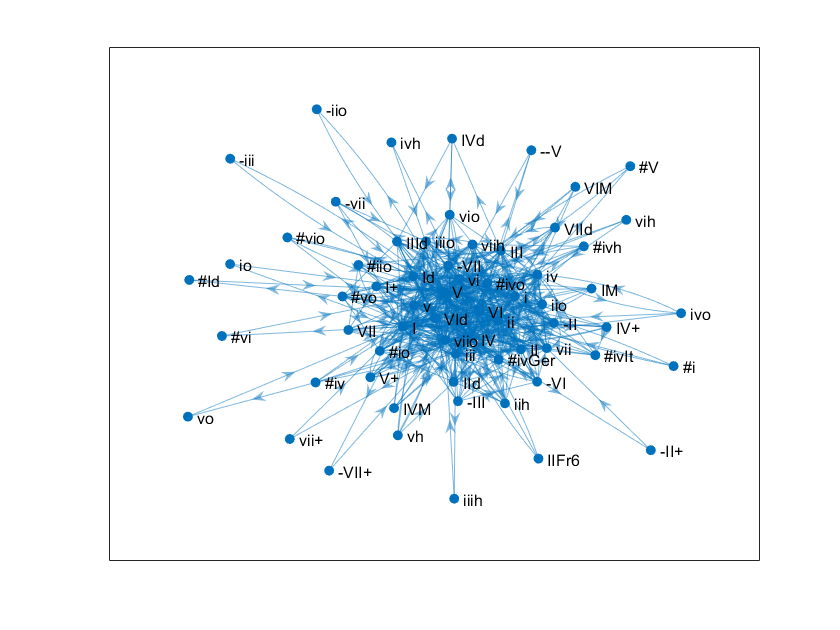

G = digraph(tab.source,tab.target,tab.Weight,'OmitSelfLoops');
figure; plot(G,'Layout','force')

G.Nodes

ans = 17×1 table
       Name   
    __________

    {'V'     }
    {'I'     }
    {'ii'    }
    {'IV'    }
    {'viio'  }
    {'vi'    }
    {'i'     }
    {'iv'    }
    {'IId'   }
    {'iii'   }
    {'#ivGer'}
    {'#ivo'  }
    {'viih'  }
    {'iih'   }
    {'I+'    }
    {'VI'    }


G.Edges

ans = 50×2 table
        EndNodes          Weight  
    _________________    _________

    {'V'}    {'I'   }      0.21153
    {'V'}    {'ii'  }     0.018358
    {'V'}    {'IV'  }     0.023981
    {'V'}    {'viio'}       0.0215
    {'V'}    {'vi'  }     0.019681
    {'V'}    {'i'   }     0.015629
    {'V'}    {'iv'  }    0.0038865
    {'V'}    {'IId' }    0.0022327
    {'V'}    {'iii' }    0.0033904
    {'V'}    {'viih'}    0.0019846
    {'V'}    {'VI'  }    0.0017365
    {'V'}    {'v'   }    0.0017365
    {'I'}    {'V'   }      0.15505
    {'I'}    {'ii'  }     0.022244
    {'I'}    {'IV'  }     0.031506
    {'I'}    {'viio'}     0.022244


nodes = table2cell(G.Nodes);
outdegrees = centrality(G,'outdegree');
out = table(nodes,outdegrees);
out = sortrows(out,'outdegrees','descend')

out = 17×2 table
      nodes       outdegrees
    __________    __________

    {'V'     }        12    
    {'I'     }         8    
    {'viio'  }         6    
    {'IV'    }         5    
    {'vi'    }         5    
    {'ii'    }         4    
    {'i'     }         2    
    {'iv'    }         2    
    {'IId'   }         1    
    {'iii'   }         1    
    {'#ivGer'}         1    
    {'#ivo'  }         1    
    {'viih'  }         1    
    {'iih'   }         1    
    {'I+'    }         0    
    {'VI'    }         0    


indegrees = centrality(G,'indegree');
in = table(nodes,indegrees);
in = sortrows(in,'indegrees','descend')

in = 17×2 table
      nodes       indegrees
    __________    _________

    {'V'     }       13    
    {'I'     }        6    
    {'viio'  }        6    
    {'ii'    }        5    
    {'IV'    }        5    
    {'vi'    }        3    
    {'i'     }        3    
    {'iv'    }        3    
    {'IId'   }        1    
    {'iii'   }        1    
    {'viih'  }        1    
    {'I+'    }        1    
    {'VI'    }        1    
    {'v'     }        1    
    {'#ivGer'}        0    
    {'#ivo'  }        0    
